# Muscle Synergy Extraction

data = MVC_normalized;
[num_samples, NoC] = size(emg); %No. of Channels corr. to No. of muscles
no_syn = 3; %will develope tests to tune this hyper-parameter

## Principal Component Analysis (PCA)

PCA extracts the principal component coefficients, also known as loadings, for the *n*-by-*p* data matrix `X`. Rows of `X` correspond to observations and columns correspond to variables. The coefficient matrix is *p*-by-*p*. Each column of `coeff` contains coefficients for one principal component, and the columns are in descending order of component variance. By default, `pca` centers the data and uses the singular value decomposition (SVD) algorithm.

Principal component scores are the representations of `X` in the principal component space. Rows of `score` correspond to observations, and columns correspond to components.

Latent represents The principal component variances, which are the singular-values of the covariance matrix of `X`.

Limitations of PCA:

- Can only capture linear relations in data

- Orthogonality of Synergies 

- Gaussian-Distributed Data

- Stationary Data 

[coeff,score, latent, tsquared, explained]=pca(data);
coeff * coeff' %checking orthonormality of singular vectors

ans =     1.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0000    1.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000    0.0000    1.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    1.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    1.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    1.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000    0.0000    0.

### Principal Components Exploration

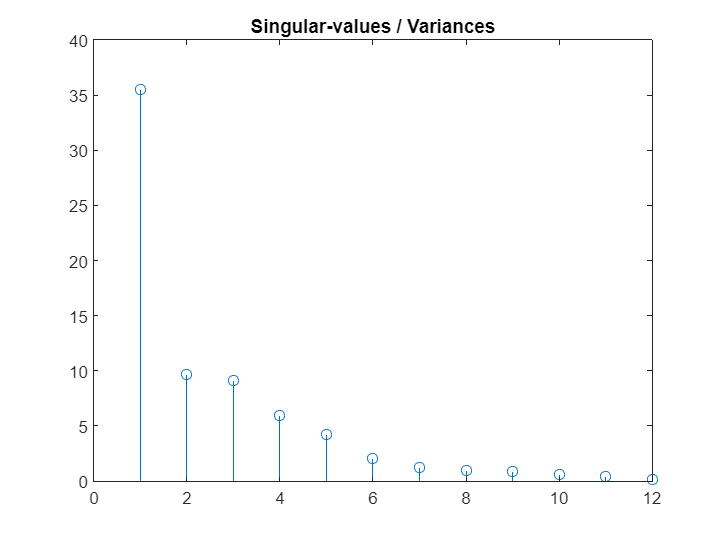

figure;
stem(latent)
title('Singular-values / Variances')

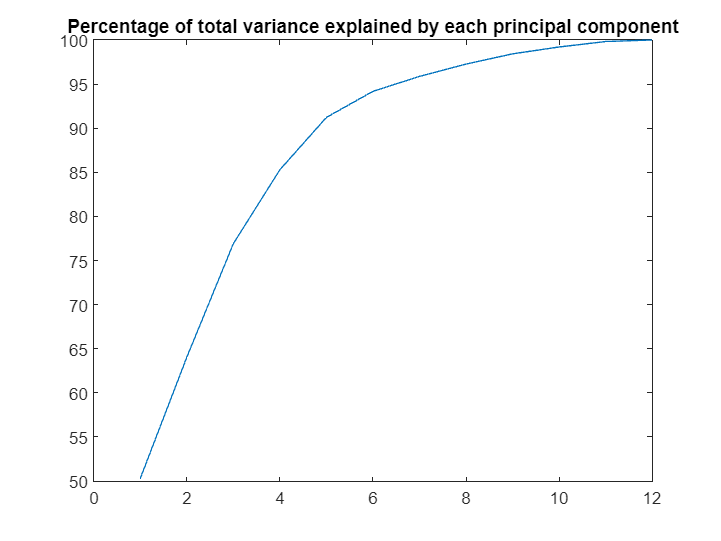

figure;
plot(cumsum(explained))
title('Percentage of total variance explained by each principal component')

### Extracting Muscle Synergies

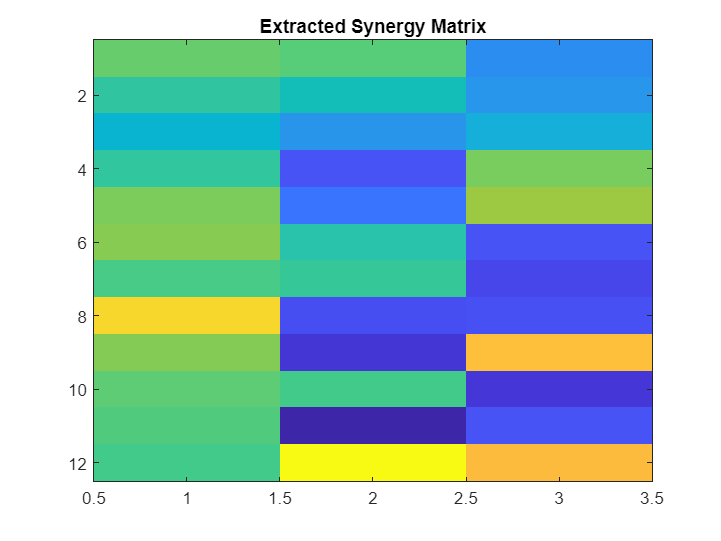

%extracting the synergy vectors and time activations
syn_mat = coeff(:,1:no_syn);
time_act = score(:,1:no_syn)';
rec_data_pca = (syn_mat*time_act)'; %reconstructed data
figure;
imagesc(syn_mat)
title('Extracted Synergy Matrix')

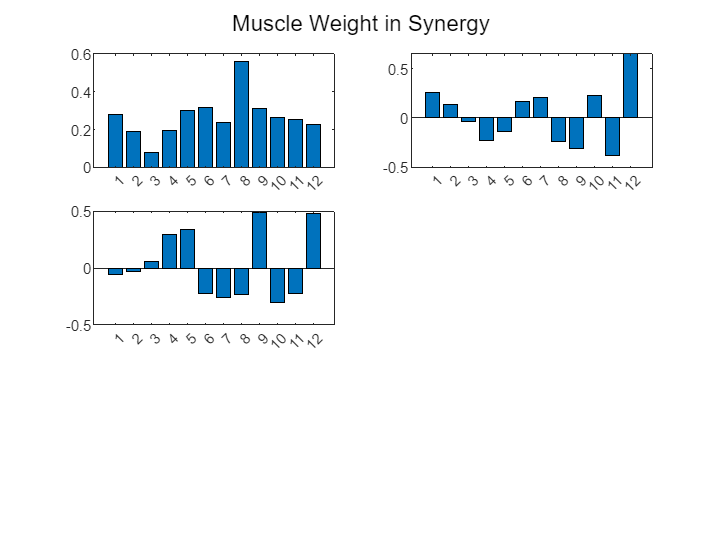

figure;
sgtitle('Muscle Weight in Synergy')
for i=1:no_syn
    subplot(3,2,i)
    bar(syn_mat(:,i))
end

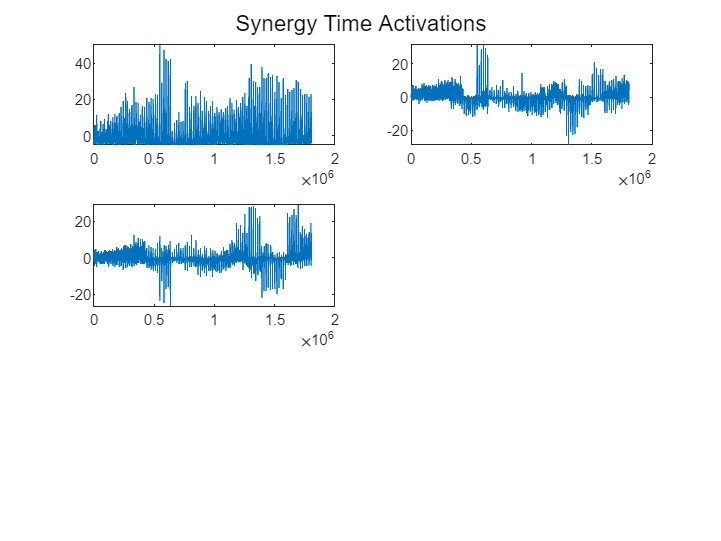

figure;
sgtitle('Synergy Time Activations')
for i=1:no_syn
    subplot(3,2,i)
    plot(time_act(i,:))
end

### Performance Metrics

res_PCA = norm(data - rec_data_pca,'fro')/sqrt(num_samples*NoC) %residual

res_PCA = 2.0914

VAF_PCA = 99.9735

VAF_PCA = vaf(data, rec_data_pca)

VAF_PCA2 =    68.1987
   62.8321
   61.2748
   74.8635
   80.6423
   77.2738
   77.4888
   78.6580
   90.5596
   80.4236


#### Two-sample Kolmogorov-Smirnov test

The two-sample Kolmogorov-Smirnov test is a nonparametric hypothesis test that evaluates the difference between the cdfs of the distributions of the two sample data vectors over the range of *x* in each data set.

it is given by the folllowing equation:


$$D=\max \left|D_k \right|$$



$$D_k =\max \left|F_l \left(x\right)-F_k \left(h\right)\right|,\;\;\;\;l=1,2,\ldotp \ldotp \ldotp ,L,\;k=1,2,\ldotp \ldotp \ldotp ,K$$


D_ks stores test results:

- h -> Hypothesis test result, returned as a logical value.

- p-> Asymptotic *p*-value of the test, returned as a scalar value in the range (0,1). `p` is the probability of observing a test statistic as extreme as, or more extreme than, the observed value under the null hypothesis

- d ->  Test statistic, returned as a nonnegative scalar value.

D_ks = zeros(3,NoC * no_syn); 
counter = 1;
for k=1:no_syn
    for l=1:NoC
        [h,p,d] = kstest2(data(:,l)', time_act(k,:));
        D_ks(1,counter) = h;
        D_ks(2,counter) = p;
        D_ks(3,counter) = d;

        counter = counter +1;
    end
end
[argvalue, argmax] = max(D_ks(3,:));
D_ks(:,argmax)

ans =     1.0000
         0
    0.7934


## Non-negative Matrix Factorization (NMF)

NMF factors the *n*-by-*m* matrix `A` into nonnegative factors `W` (*n*-by-`k`) and `H` (`k`-by-*m*). The factorization is not exact; `W*H` is a lower-rank approximation to `A`. The factors `W` and `H` minimize the root mean square residual between `A` and `W*H`.

Limitations of NMF:

- Does not assume normality 

- Does not impose orthogonality on the extracted synergies but they are constrained to be independent

- Imposes a non-negativity constraint on the extracted synergies

[W,H] = nnmf(data,no_syn);

### Extracting Muscle Synergies

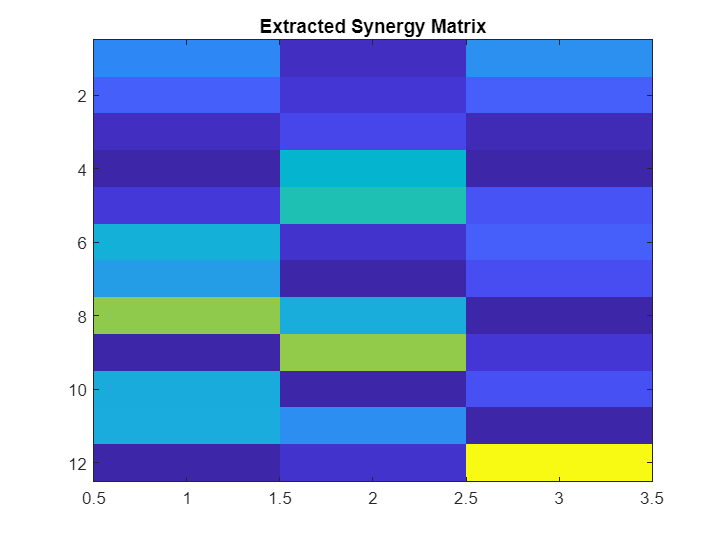

rec_data_NMF = W * H;
figure;
imagesc(H')
title('Extracted Synergy Matrix')

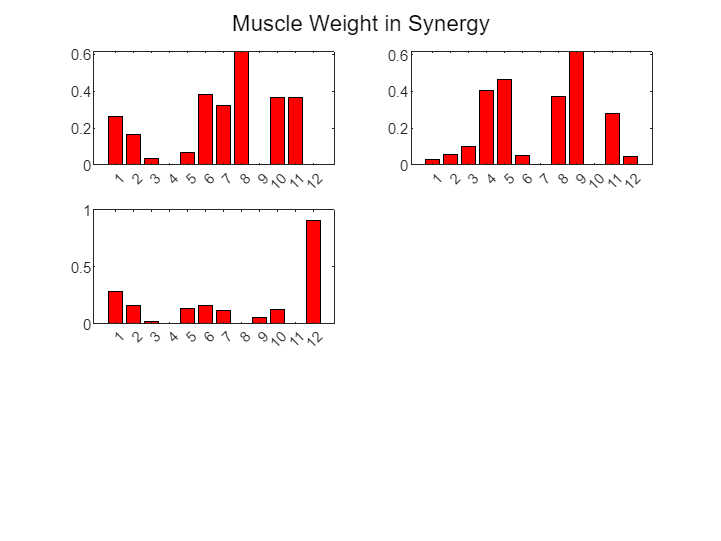

figure;
sgtitle('Muscle Weight in Synergy')
for i=1:no_syn
    subplot(3,2,i)
    bar(H(i,:),'r')
end

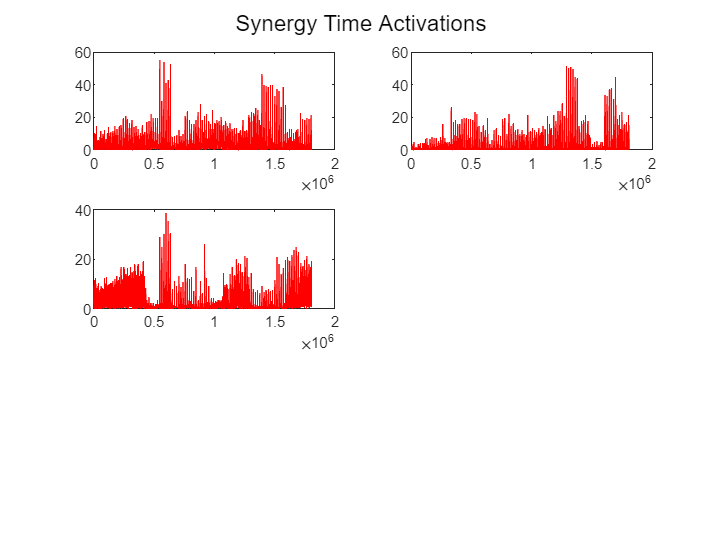

figure;
sgtitle('Synergy Time Activations')
for i=1:no_syn
    subplot(3,2,i)
    plot(W(:,i),'r')
end

### Performance Metrics

res_NMF = norm(data - rec_data_NMF,'fro')/sqrt(num_samples*NoC) %residual

res_NMF = 1.2187

VAF_NMF = vaf(data, rec_data_NMF)

VAF_NMF =    64.8962
   59.1829
   59.1774
   78.0143
   82.3295
   74.4763
   71.6895
   77.0196
   92.1322
   74.4213


### Two-sample Kolmogorov-Smirnov test

NMF_D_ks = zeros(3,NoC * no_syn); 
counter = 1;
for k=1:no_syn
    for l=1:NoC
        [h,p,d] = kstest2(data(:,l)', W(:,k));
        NMF_D_ks(1,counter) = h;
        NMF_D_ks(2,counter) = p;
        NMF_D_ks(3,counter) = d;

        counter = counter +1;
    end
end
[argvalue, argmax] = max(NMF_D_ks(3,:));
NMF_D_ks(:,argmax)

ans =     1.0000
         0
    0.6834


## Independent Component Analysis (ICA)

Independent component analysis (ICA) is a statistical method for separating a multivariate signal into additive subcomponents. It converts a set of vectors into a maximally independent set.

Maximal independence means that we need to:

- Minimize mutual information between independent components or

- Maximize non-Gaussianity between independent components

Limitations of ICA:

- Each measured signal is a linear combination of the sources

- The source signals are statistically independent of each other

- The values in each source signal have non-Gaussian distribution

One measurement of non-Gaussianity can be kurtosis. Kurtosis measures a distribution’s “peakedness” or “flatness” relative to a Gaussian distribution. When kurtosis is equal to zero, the distribution is Gaussian. For positive kurtosis, the distribution is “spiky” and for negative, the distribution is “flat”.

To maximize the non-Gaussianity of $w^T X$  we can maximize the absolute value of kurtosis:


$$\max \left|\mathrm{kurt}\left(w^T X\right)\right|$$


To do that, we can use the FastICA Algorithm. FastICA is an iterative algorithm that uses a non-linear optimization technique to find the independent components.

[wieghtingFn,synergyMatrix, ~] = fastica(data','lastEig',no_syn,'verbose','off');

### Extracting Muscle Synergies

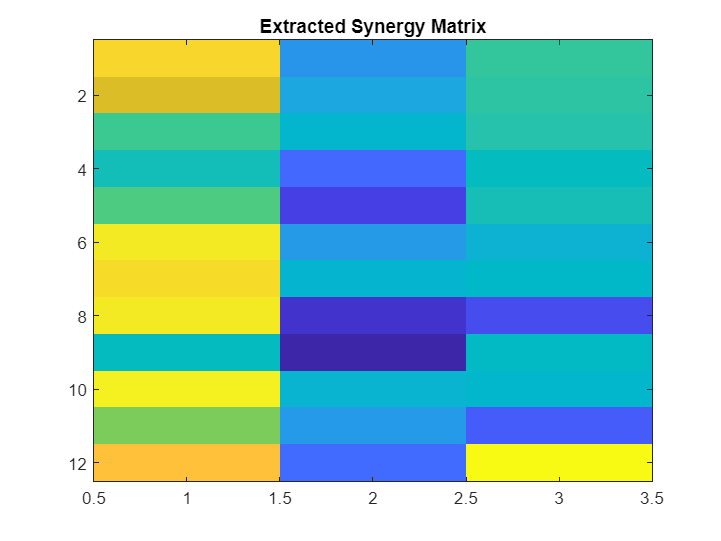

rec_data_ICA = (synergyMatrix * wieghtingFn)';
figure;
imagesc(synergyMatrix)
title('Extracted Synergy Matrix')

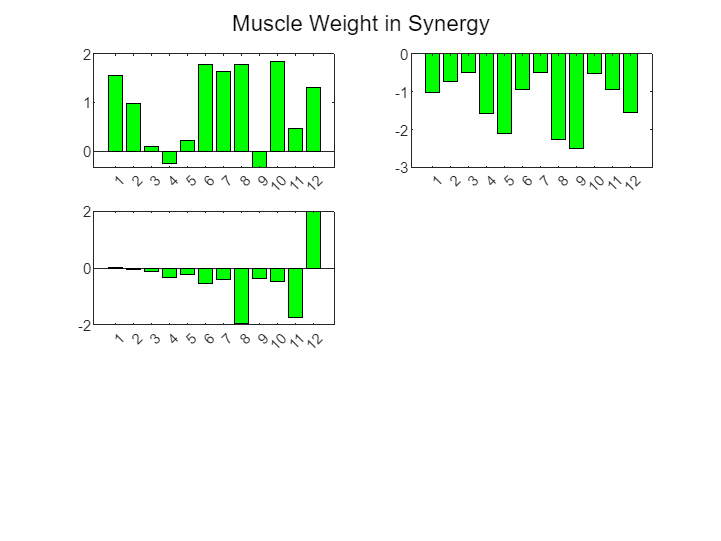

figure;
sgtitle('Muscle Weight in Synergy')
for i=1:no_syn
    subplot(3,2,i)
    bar(synergyMatrix(:,i),'g')
end

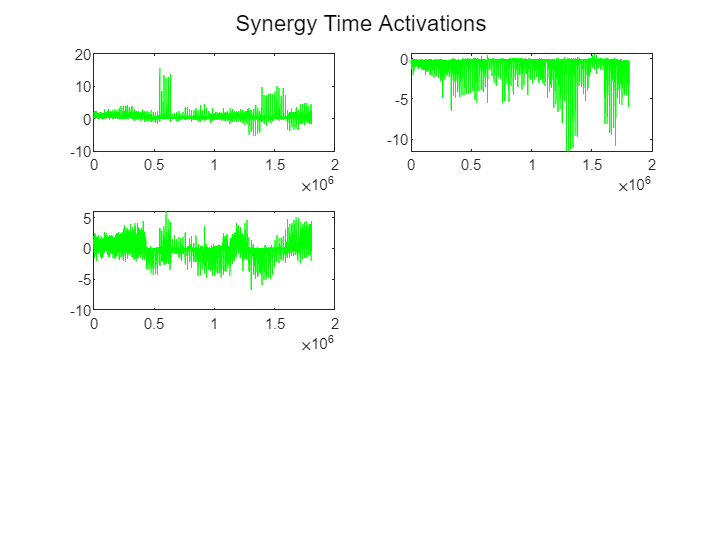

figure;
sgtitle('Synergy Time Activations')
for i=1:no_syn
    subplot(3,2,i)
    plot(wieghtingFn(i,:),'g')
end

### Performance Analysis

res_ICA = norm(data - rec_data_ICA,'fro')/sqrt(num_samples*NoC) %residual

res_ICA = 1.2325

VAF_ICA = vaf(data, rec_data_NMF)

VAF_ICA =    64.8962
   59.1829
   59.1774
   78.0143
   82.3295
   74.4763
   71.6895
   77.0196
   92.1322
   74.4213


### Two-sample Kolmogorov-Smirnov test

ICA_D_ks = zeros(3,NoC * no_syn); 
counter = 1;
for k=1:no_syn
    for l=1:NoC
        [h,p,d] = kstest2(data(:,l)', wieghtingFn(k,:));
        ICA_D_ks(1,counter) = h;
        ICA_D_ks(2,counter) = p;
        ICA_D_ks(3,counter) = d;

        counter = counter +1;
    end
end
[argvalue, argmax] = max(ICA_D_ks(3,:));
ICA_D_ks(:,argmax)

ans =     1.0000
         0
    0.9999
